# Example 1: Analysis of a TPMS unit cell

## 1.1 Defining a TPMS unit cell parametrically

The first step is to set the structure **equation**, the most common TPMS-like functions can be accessed using their name. 

- 'Primitive', 'Diamond', 'Gyroid', 'Neovius', 'IWP', 'FRD'. 

- Other example functions include 'Sphere', 'P-normCube' and 'Taurus'

- Alternatively, a custom **equation** can be defined such as: *equation = @(x,y,z) cos(x).*sin(y)+cos(y).*sin(z)+cos(z).*sin(x)+(2*y-1);*

Next the **type** needs to be set - this sets how the equation is converted into a solid. 

- network' (default), creates a more skeletal/strut like structure at a target volume fraction. 

- 'surface' creates a thickened surface

- 'single' creates a skeletal/strut-like structure using a specified isovalue as an upper threshold

- 'double' is reccomended for more advanced users, and utilises a lower and upper isovalue to create a more wide range of structures

Finally, **either** the target volume fraction **vf**, and/or the isovalue **v**, needs to be set. Volume fractions (**vf**) should be in the range of 0 to 1. Note that for custom equations, **vf** will be used as the isovalue, and not mapped to approximate volume fraction.

- Network-type structures can input a target volume fraction '**vf**',  

- Surface-type can input a target volume fraction '**vf**' and mid-plane isovalue '**v**'

- Single-type directly inputs a single isovalue '**v**'

- Double-type uses '**vf**' and '**v**' as the lower and upper bounding isovalues

To create variable density/graded structures, either **v** or **vf** can be multiple inputs. Linear gradients should be input as an (Lx1) vector, 2D gradients should be an (LxM) matrix and 3D gradients should be (LxMxN) which will be remapped to stretch across bulk volume.

Additional inputs should also be defined, any inputs left blank will result in a default (safe) value being used. These values are the ordered inputs for the **TPMS** class constructor to create the TPMS object (**myTPMS**).

- The resolution for the meshgrid (**res**), 

- the size of the structure (**sz**), 

- number of unit cells (**ncells**), 

- rotations (**Reuler**) 

- phase offsets (**offset**) 

clear all
equation = "Gyroid"; %"Gyroid","Diamond","Primitive", "Neovius", "IWP", "FRD"
%equation = @(x,y,z) cos(x).*sin(y)+cos(y).*sin(z)+cos(z).*sin(x)+(2*y-1);
type = "network"; % Types: "network","surface","single", "double"
vf = 0.3; % Target Volume Fraction between 0 and 1 - (used for network and surface)
v = [];% Isovalue(s) input as a scalar, vector, 2D or 3D array for network and surface (will be resampled uniformly). (2x1)
res = [25 25 25]; % Resolution - (number of voxels per edge in x,y,z)
sz = [10 10 10]; % Cell size - (size of the unit cell in x,y,z)
ncells = [1 1 1]; % Number of cells - (in x,y,z)
Reuler = [0 0 0]; % Euler Rotaions - (rotions in degrees pitch,roll,yaw)
offset = [0 0 0]; % Phase offset - (shift phase in x,y,z)

%TPMS(equation,type,v,vf,res,cellSize,ncells,Rxyz,offset)
myTPMS = TPMS(equation,type,v,vf,res,sz,ncells,Reuler,offset);

## 1.2 Calculating the properties of the structure

After defining the structure, it must be generated and analysed.

Depending on the required properties, this involves potentially generating the following representations of the unit cell:

- a **v3field** object for storing 3D volumetric data/fields

- a **surfaceMesh** object which captures information about the boundary surface

- a **metrics** object is created to simplify the outputs to scalar values which can be used to rapidly compare properties of different structures.

To request calculation of properties, the **myTPMS.properties**(field,mechanical,surfaceMesh,curvaturemethod) method is used, the inputs turn on and off various calculation steps, which can skip steps if certain analysis information is not required. A boolean 1 or 0 will specify is this proeprty is required.

- **field**, is required for all subsequent operations with TPMS, this will automatically be turned on if later steps are requested

- **mechanical**, applies sets of periodic boundary conditions to create the cauchy stiffness tensor and homogenise the unit cell

- **surfaceMesh** requests that this be generated using matlab's inbuild isosurface function. 

- **curvature** allows the user to define which method which be used to approximate/calculate the curvature of the surface. The methods which have been included are 'patch', 'surfaceMesh' or 'none'. (more detailed explanations of these algrithms can be found in example 2.)

Turning on more requested properties will increase the computational time - particulaly at higher resolutions. Many of these problems/algorithms have non-linear scaling so be careful when increasing resolution!

calculateFields = 1;  % 1 or 0 to turn on or off.
calculateMechanical = 1;  % 1 or 0 to turn on or off.
calculatesurfaceMesh = 1; % 1 or 0 to turn on or off.
curvatureMethod = 'implicit'; % 'patch', 'surfaceMesh', 'none'

myTPMS = myTPMS.properties(calculateFields,calculateMechanical,calculatesurfaceMesh,curvatureMethod);

Once the properties have been calculated these various properties can be accessed and viewed using dot indexing or flattened to combine important metrics for the structure using TPMS.export.

output = myTPMS.export;

## 1.3 Plotting and visulisation

There are a range of different ways to plot/properties to visualse a generated structure. The syntax for using this function is **plot(TPMS,ax,plottype,property1,property2,opts).**

The **plottype** may be defined using any of the following:

- "surfaceMesh"(default),

- "voxel",

- "orthoslice",

- "slice",

- "histogram",

- "histogram2",

- "polemap",

- "tensor"

By default, the first input is the axis handle **ax** which the plot should be created on. This allows users to create the plots on subfigures. Below are examples showing how to create a new figure and use "gca" to select the current (just created) axis

Many of the plotting options can take inputs for setting which property/properties should be displayed as the colour of the figure.  To find the complete list of these the user can inspect the fields of the relevant data type the user can try the commands such as **myTPMS.F.property**, **myTPMS.FV.Fproperty** and **myTPMS.FV.Fproperty** to return the properties avaliables. Some of the common examples are below.

- [], monotone grey

- "inclination" Inclination angle

- "GC", 

When accessiong a property the property name (case-insensitive) will be compared to the first word. so calling "inclination", "Inclination" or "Inclination angle in deg^o" will all access the inclination property. The complete string passed in will become the label for the colorbar.

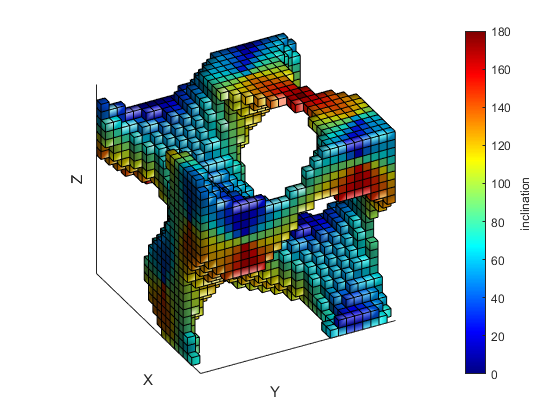

% Example 1: Voxel plot of no proeprty ([])
opts.fancy = 1; %Use fancy style lighting/shading
figure; axesVoxel = myTPMS.plot(gca,"voxel","inclination ",[],opts);

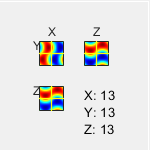



% Example 2: Create orthosslice viewer
figure; axesSlice = myTPMS.plot(gca,"orthoslice","U");

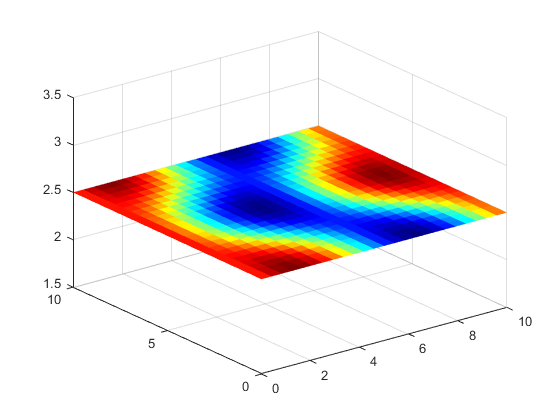


% Example 3: XY-Slice of the TPMS function (U) at a given z-height fraction
opts.slice = 25; % Define Z-slice height
figure; axesXYslice = myTPMS.plot(gca,"slice","U",[],opts);

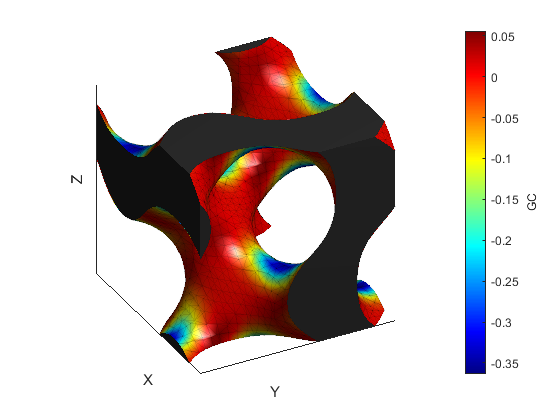


% Example 4: A rendering of the isosurface mesh, coloured by a property
figure; axesSurface = myTPMS.plot(gca,"surfaceMesh","GC",[],opts);

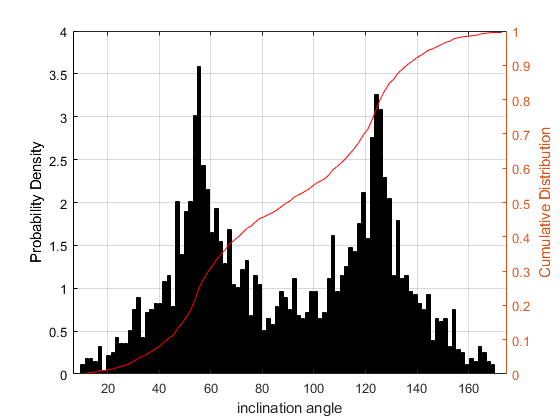


% Example 5: Histogram shows the distribution of a property (area-weighted)
figure; axesHist = myTPMS.plot(gca,"histogram","inclination angle");

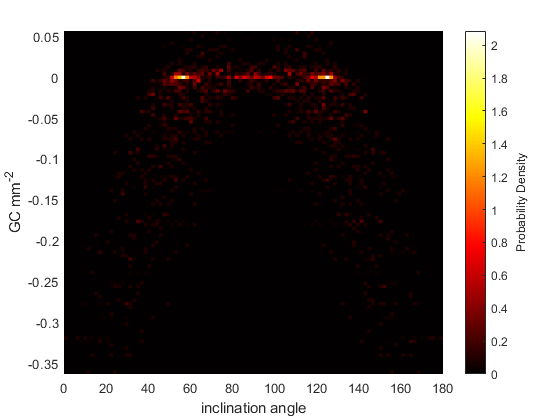


% Example 6: 2-Variable Histogram shows heatmap and how 2 properties interact
figure; axesHist2 = myTPMS.plot(gca,"histogram2","inclination angle","GC mm^-^2",100);

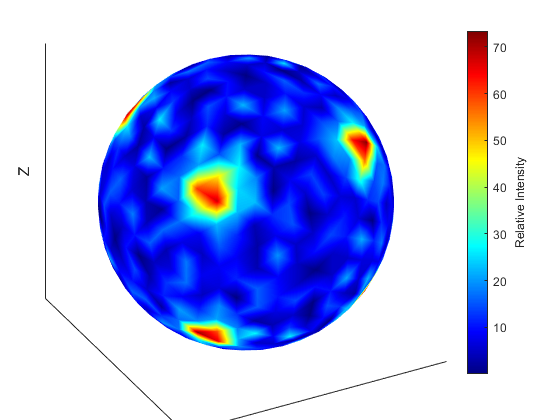


% Example 7: Pole-map of surface orientations
figure; axesPolemap = myTPMS.plot(gca,"polemap",[],[]); % Pole-map of surface orientations

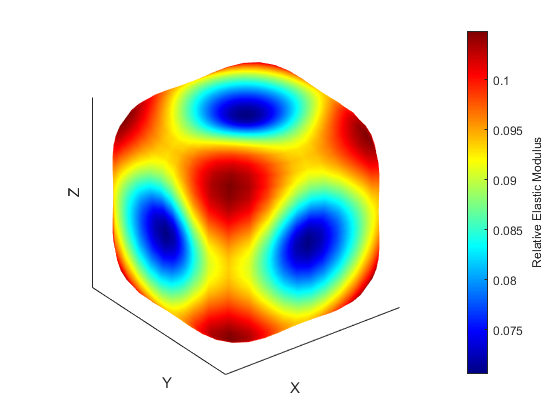


% Example 8: Stiffness tensor representation (requires calculateMechanical to be turned on)
figure; axesTensor = myTPMS.plot(gca,"tensor",[],[]); % Stiffness tensor representation

## 1.4 Exporting data

There are a number of export options which have been integrated. An .INP file may be exported from the v3field. Or the surface may be exported as a .stl file. In future more options for exporting will be made avaliable.

myTPMS.F.exportINP('outputs/myTPMS.inp'); % INP Export (path+filename)
myTPMS.FV.exportSTL('outputs/myTPMS.stl'); % STL Export (path+filename)